# The Diffusion Equation

The diffusion equation 


$$\frac{\partial C}{\partial t} = {\cal D}\frac{\partial^2C}{\partial x^2}$$


can be solved using the FTCS scheme.

## The FTCS Scheme

Here we shall solve the one-dimensional diffusion equation using the FTCS scheme and using a Gaussian profile as the initial condition. Here we expect to see the profile spread out over time and the maximum of the profile decrease. 

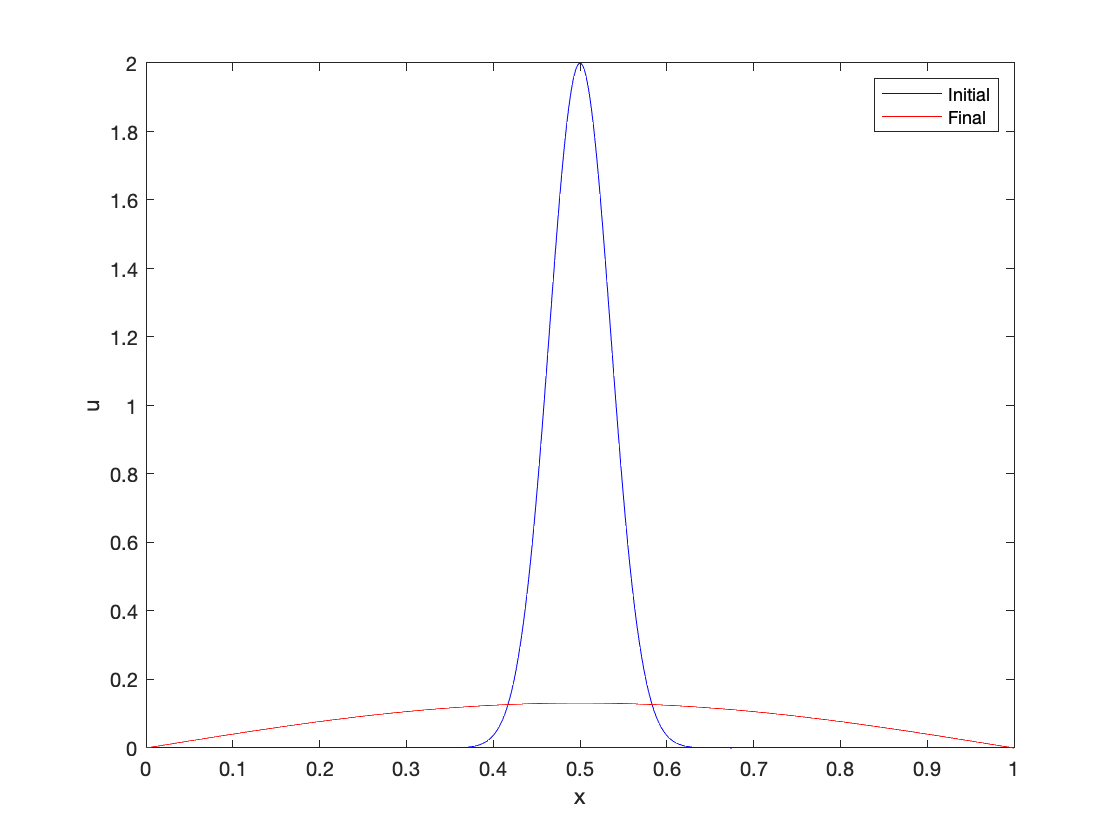

% Define the diffusion coefficient (D)
diff_coeff = 1.0;

% Define the Courant number (D*delta_t)/(delta_x)^2
alpha = 0.5;

% Define the grid
x_min = 0.0;
x_max = 1.0;
n_space = 500;

x       = linspace(x_min, x_max, n_space);
delta_x = x(2) - x(1);

t_min = 0.0;
t_max = 0.1;

t  = t_min : dt : t_max;
dt = alpha * delta_x * delta_x / diff_coeff;

n_x = length(x);
n_t = length(t);

% Pre-allocate storage: 
u_solution = zeros(n_t, n_x);

% Set up initial condition. We will take this to be a Gaussian
my_gauss = @(x, a, m, s) a * exp(-((x-m)/s).^2);

gauss_amplitude = 2.0;
gauss_mean      = mean(x);
gauss_var       = 0.05;

u_solution(1,:) = my_gauss(x, gauss_amplitude, gauss_mean, gauss_var);

% Solve the equation
for i_step = 2 : n_t
    
    u_solution(i_step,:) = FTCSStepDiffMMEES(u_solution(i_step-1,:), courant_num);
    
end

figure
plot(x, u_solution(1,:), 'b', x, u_solution(end,:), 'r')
xlabel('x')
ylabel('u')
legend('Initial', 'Final')

***Exercise:**** Investigate what happens to the solution as you increase and decrease the number of grid points and the time interval *`dt`

***Exercise: ****Investiage what happens to the solution if you make *`alpha` larger than 1.